# Receiver Operating Characteristic (ROC) Curves

ROC curves provide a way to assess a new diagnostic test. This applies to tests that give a numercial **score **and from this score we want to classify a patient as positive for disease or negative.The aim is often to characterise a new test that we hope has some useful feature such as being cheaper, easier, fewer side-effects etc. During this assessment phase, we need a reference standard to give what we assume is a 'ground truth' **label**. Example scores could be the intensity in an image region or the concentration of a compoud in a blood sample. Example positive labels could be 'malignant' or 'sick' and negative labels might be 'benign' or 'healthy'. If the new test is to be used, we will need to choose a threshold score. We will classify all scores above this threshold (or operating point) as positive and all below as negative. The ROC plot shows how the test performs for different possible values of the threshold score. The area under the curve (AUC) provides an overall measure of how good the test is (the closer the AUC is to 1, the better).

The reason the AUC is less than 1 is related to the fundamental problem that some scores for positive and negative patients overlap. The result is that for most useful choices of a threshold, there will be some false negatives and some false positives. This is perhaps best visualised first using a histogram.

Create an illustrative example from normal distributions with the mean score being 10 for positives being and 5 for negatives. Intuitively, we expect the threshold to be somewhere between 5 and 10. 

% Simualate scores for positive and negative patients
scores_pos = 10 + 3*randn([200 1]) ; % scores for positive (sick) patients
scores_neg =  5 + 3*randn([250 1]) ; % scores for negative (healthy) patients

scores_all = [scores_pos(:) ; scores_neg(:)] ;
labels_all = cat(1,repmat('Positive',[length(scores_pos) 1]), repmat('Negative',[length(scores_neg) 1])) ;

disp("Median scores: positive " + median(scores_pos) + ", negative "+median(scores_neg))

Median scores: positive 10.2134, negative 4.5503


It is useful to visualise the data using histograms and/or box plots. These give an idea of the distribution and overlap among the scores. The tool tip functionality can be used on the box plot to read off medians, quartile ranges etc. The histogtram is here shown orientated horizontally to help visual comparison with the box plot. Use the arrow at the top right of the figure to open it in a separate window for better viewing. 

figure
tiledlayout(2,2)
% Visualise the scores using a histogram
axhist = nexttile([1 1]) ;
histogram(scores_pos,'Orientation','horizontal','FaceColor',[1 0 0])
hold on
histogram(scores_neg,'Orientation','horizontal','FaceColor',[0 0 1])
ylabel('Score'), xlabel('Frequency')
grid on, ylim([min(scores_all) max(scores_all)])

% Visualise using a boxplot (ignore warning)
axbox = nexttile([1 1]) ;
boxplot(scores_all, labels_all, 'Notch','on')

grid on, ylim([min(scores_all) max(scores_all)])

These plots are informative - the histogram shows that the overlap of scores is more than might be expected from the box plot. . 

Now let's plot the ROC curve, we use the `perfcurve` command (not `roc`) and tell it the name of the positive class (here `'Positive'`). Also, we will set the Data Tip so that we can get the threshold score for each point if we hover over the curve. 

% ROC Curve
axroc = nexttile([1 2]) ;
[X,Y,T,AUC,OPTROCPT] = perfcurve(labels_all, scores_all,'Positive','NBoot',1000) ;
% Columns are 1 mean, 2 lower confidence, 3 upper confidence
hp = plot(X(:,1),Y(:,1),'LineWidth',2) ;
hold on
plot([0 1],[0 1],'LineWidth',1) % diagonal line
xlabel('False positive rate (1-Specificity)')
ylabel('True positive rate (Sensitivity)')
grid on

% Set data tip so that it also shows the thresholds at each point
dtt = hp.DataTipTemplate;
dtt.DataTipRows(1).Label = 'FPR' ;
dtt.DataTipRows(2).Label = 'TPR' ;
row = dataTipTextRow('Threshold',T(:,1)) ;
dtt.DataTipRows(end+1) = row;

Point confidence intervals were also calculated by `perfcurve` using bootstrapping and these allow us to give the confidence intervals for the AUC.

title(['AUC ',num2str(AUC(1),2) ,' (', num2str(AUC(2),2), ' ', num2str(AUC(3),2), ')'])

In practice, we may choose an operating point aiming for a certain sensitivity. Here we find the closest point on the curve to the 90% true positive rate (sensitivity) and then plot the corresponding confidence intervals.

% Find the index loc of the ROC point closest to TPR = 90%
[~, loc] = min(abs(Y(:,1)-0.9)) ; % loc is index of point closest to TPR of 0.9
errorbar(X(loc,1), Y(loc,1), Y(loc,1)-Y(loc,2), Y(loc,3)-Y(loc,1), ...
    X(loc,1)-X(loc,2), X(loc,3)-X(loc,1), 'LineWidth',2)

disp(['Threshold score of ',num2str(T(loc,1),3),' at TPR of ',...
    num2str(Y(loc,1),3),', Specificity of ',num2str(1-X(loc,1),3)])

Threshold score of 6.63 at TPR of 0.9, Specificity of 0.772


% bring curve to front so that datatip works well
uistack(hp,'top')

The distributions of the positive and negative scores are quite well separated in this example, giving a high AUC and small point confidence intervals.

Plot the threshold score corresponding to the point closest to 90% TPR  as horizontal lines on the histogram and box plots.

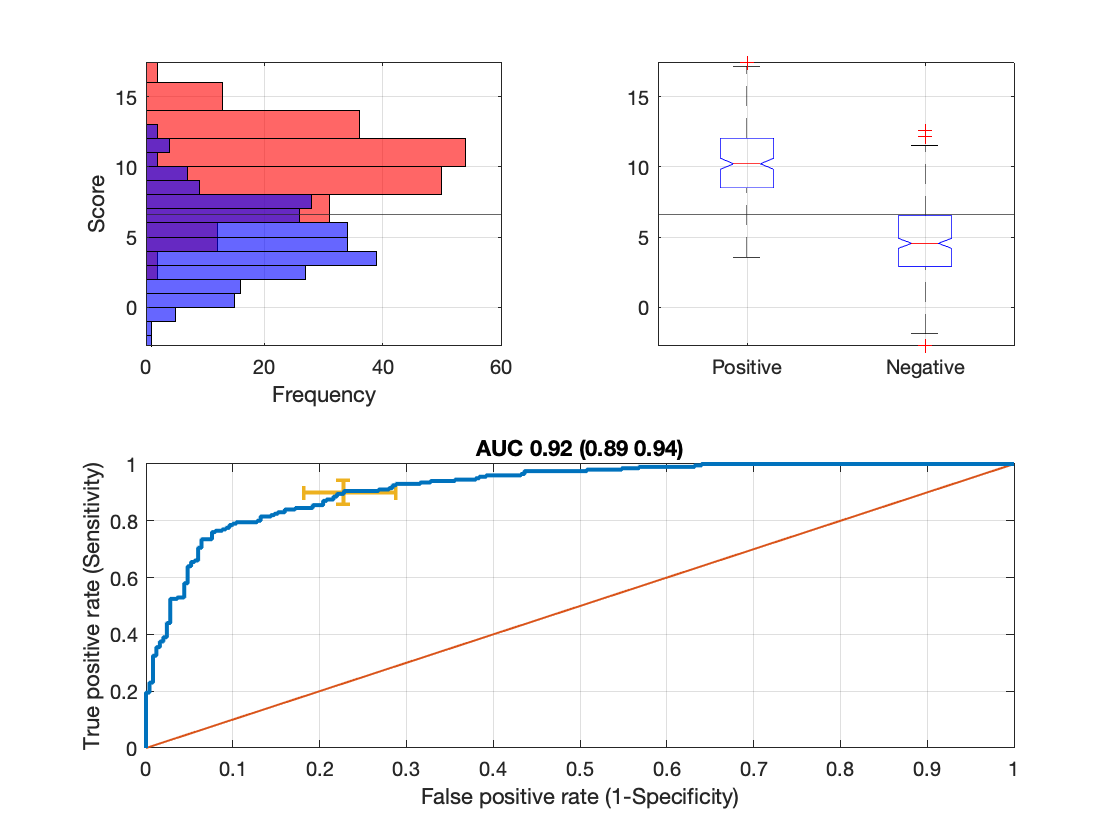

% Show on histogram and boxplot where this threshold score is located
yline(axbox, T(loc,1))
yline(axhist,T(loc,1))

© 2021 David Atkinson